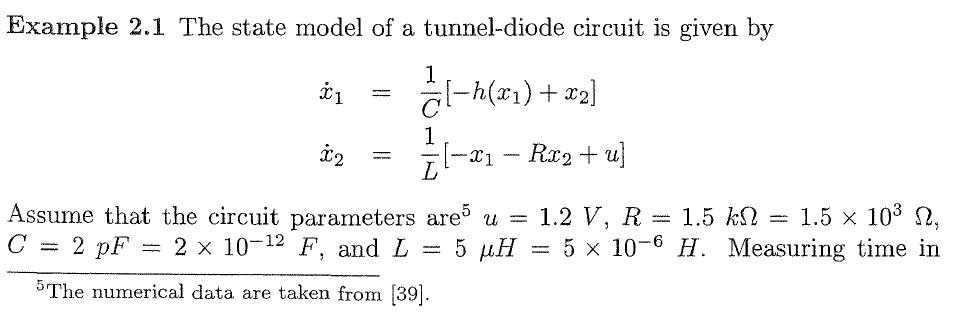

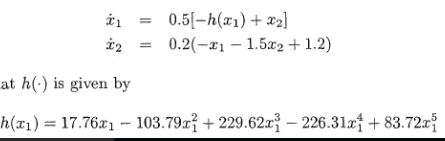

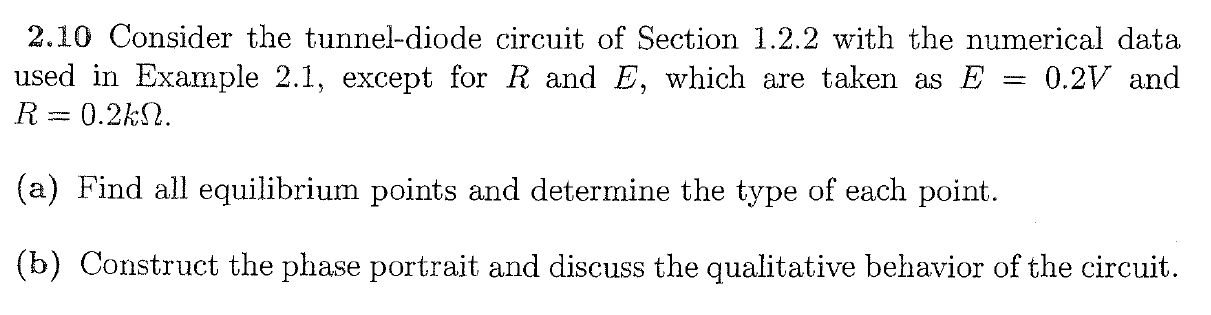

clear;
syms a positive
syms b nonzero
syms x1 x2

E = 0.2;
R = 0.2;
C = 2;
L = 5;

% find equilibrium points
h = poly2sym([83.72 -226.31 229.62 -103.79 17.767 0], x1);
f1 = 1/C*(-h + x2);
f2 = 1/L*(-x1 - R*x2 + E);

sln = solve([f1==0, f2==0], [x1 x2]);
vpa(sln.x1,2) % variable precision (2 sig figs)

$$ans = \left(\begin{array}{c} 0.057\\ 0.32+0.29\,\mathrm{i}\\ 0.32-0.29\,\mathrm{i}\\ 1.0+0.34\,\mathrm{i}\\ 1.0-0.34\,\mathrm{i} \end{array}\right)$$

vpa(sln.x2,2)

$$ans = \left(\begin{array}{c} 0.72\\ -0.6-1.5\,\mathrm{i}\\ -0.6+1.5\,\mathrm{i}\\ -4.0-1.7\,\mathrm{i}\\ -4.0+1.7\,\mathrm{i} \end{array}\right)$$


% Jacobian
J = jacobian([f1 f2], [x1 x2]);
for i=1:numel(sln.x1)

    % skip the imaginary eq. points
    s1 = vpa(sln.x1(i));
    s2 = vpa(sln.x2(i));
    if ~isreal(s1) || ~isreal(s2)
        continue
    end
    
    disp('Equilibrium Point: ')
    disp(vpa([s1 s2], 2))
    A = subs(J,[x1 x2], [s1 s2]);
    disp('Eigenvalues: ')
    disp(vpa(eig(A), 2))
end

Equilibrium Point: 


$$\left(\begin{array}{cc} 0.057 & 0.72 \end{array}\right)$$

Eigenvalues: 


$$\left(\begin{array}{c} -0.065\\ -4.0 \end{array}\right)$$

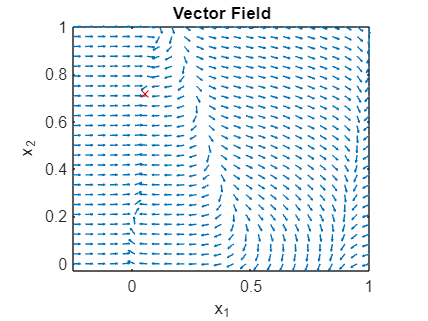

% Create vector field
x = linspace(-0.25,1,25);
y = linspace(0,1,25);
[X,Y] = meshgrid(x,y);

H = polyval([83.72 -226.31 229.62 -103.79 17.767 0], X);
DX = 1/C*(-H + Y);
DY = 1/L*(-X - R*Y + E);

% make arrows the same length
N = sqrt(DX.^2 + DY.^2);
quiver(X,Y,DX./N,DY./N,0.5);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")

hold on;
plot(0.057, 0.72, 'rx')
hold off;